# Actividad 1: Velocidades lineares y angulares

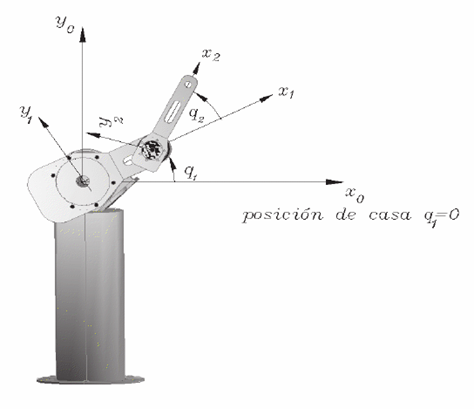

Vector de velocidades linear y angular:

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas (No tienen un valor específico)
syms th1(t) th2(t) th3(t) l1 l2 l3 t  

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1 th2 th3];
disp('Coordenadas articulares');

Coordenadas articulares


pretty (Q);

(th1(t), th2(t), th3(t))




%Creamos el vector de velocidades articulares
Qp= diff(Q, t); %Utilizo diff para derivadas cuya variable de referencia no depende de otra: ejemplo el tiempo
disp('Velocidades articulares');

Velocidades articulares


pretty (Qp);

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /




%Número de grado de libertad del robot
GDL= size(RP,2); %***Siempre se coloca 2, ya que indica la dimensión de las columnas
GDL_str= num2str(GDL);%Convertimos el valor numérico a una cadena de carácteres tipo string

%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1);
           l1*sin(th1);
                     0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0; %*** Análisis de robot péndulo
           sin(th1)  cos(th1)  0;
           0         0         1];

%Articulación 2 
%Posición de la junta 2 respecto de 0
P(:,:,2)=[l2*cos(th2); 
          l2*sin(th2);
          0];

%Matriz de rotación de la articulación 2 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0; %*** Análisis de robot péndulo
           sin(th2)  cos(th2)  0;
           0         0         1];

%Articulación 3 
%Posición de la junta 2 respecto de 0
P(:,:,3)=[l3*cos(th3); 
          l3*sin(th3);
          0];

%Matriz de rotación de la articulación 2 respecto a 0
R(:,:,3)= [cos(th3) -sin(th3)  0; %*** Análisis de robot péndulo
           sin(th3)  cos(th3)  0;
           0         0         1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%****

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%*****

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); %*****

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);

for i = 1:GDL
    i_str= num2str(i);
    %Locales
    %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);  %Caso específico cuando i=1 nos marcaría error en try
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i));
%Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
%matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%Calculamos el jacobiano lineal y angular de forma analítica
%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if ((RP(k)==0)|(RP(k)==1))%Casos: articulación rotacional y prismática

       %Para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));%*****
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
    else         %Para las articulaciones prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - #1 - l2 sin(th1(t) + th2(t)), - #1 - l2 sin(th1(t) + th2(t)), -#1 \
|                                                                                      |
|  l1 cos(th1(t)) + #2 + l2 cos(th1(t) + th2(t)),   #2 + l2 cos(th1(t) + th2(t)),   #2 |
|                                                                                      |
\                        0,                                       0,                0  /

where

   #1 == l3 sin(th1(t) + th2(t) + th3(t))

   #2 == l3 cos(th1(t) + th2(t) + th3(t))




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 1, 1 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ - #4 (l3 sin(#1) + l2 sin(#2)) - #5 (l1 sin(th1(t)) + l3 sin(#1) + l2 sin(#2)) - l3 #3 sin(#1) \
|                                                                                                |
|  #4 (l3 cos(#1) + l2 cos(#2)) + #5 (l1 cos(th1(t)) + l3 cos(#1) + l2 cos(#2)) + l3 #3 cos(#1)  |
|                                                                                                |
\                                                0                                               /

where

   #1 == th1(t) + th2(t) + th3(t)

   #2 == th1(t) + th2(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /

